# Funciones de transferencia

clc; close all; clear
syms K a b s
assume(K ~= 0)                               % Con K = 0 no controlamos nada. K < 0 se invierte la cons.
Gc = collect(K*(a*s + 1)*(b*s + 1)/s);       % Controlador
Gp = collect(2*(s + 2)/((s + 1)*(s + 10)));  % Planta
Gr = collect(Gc*Gp/(1 + Gp*Gc));             % CL respecto de la referencia
Gd = collect(Gp/(1 + Gp*Gc));                % CL respecto de la perturbación

### Función de transferencia del controlador Gc

disp(Gc)

$$\frac{\left(K\,a\,b\right)\,s^{2}+\left(K\,a+K\,b\right)\,s+K}{s}$$

Esto es equivalente a la función de transferencia de un controlador PID, pero en este caso las constantes del PID están acopladas entre sí.

### Función de transferencia de la planta Gd

disp(Gp)

$$\frac{2\,s+4}{s^{2}+11\,s+10}$$

# Función de transferencia CL respecto de la referencia Gr

disp(Gr)

$$\frac{\left(2\,K\,a\,b\right)\,s^{3}+\left(2\,K\,a+2\,K\,b+4\,K\,a\,b\right)\,s^{2}+\left(2\,K+4\,K\,a+4\,K\,b\right)\,s+4\,K}{\left(2\,K\,a\,b+1\right)\,s^{3}+\left(2\,K\,a+2\,K\,b+4\,K\,a\,b+11\right)\,s^{2}+\left(2\,K+4\,K\,a+4\,K\,b+10\right)\,s+4\,K}$$

**No tiene error de estado estacionario ante un escalón en la referencia en tanto sea** $K\neq0$

**Dado que** $\lim_{s\rightarrow 0} G_r = 1$

# Función de transferencia CL respecto de la perturbación Gd

disp(Gd)

$$\frac{2\,s^{2}+4\,s}{\left(2\,K\,a\,b+1\right)\,s^{3}+\left(2\,K\,a+2\,K\,b+4\,K\,a\,b+11\right)\,s^{2}+\left(2\,K+4\,K\,a+4\,K\,b+10\right)\,s+4\,K}$$

**El sistema tiene una respuesta de estado estacionario nula ante un escalón de perturbación.**

# Analisis

Ambas funciones de transferencia son de orden 3, entonces, para hacer la comparación con el sistema de segundo orden vamos a poner todos polos a la misma frecuencia natural no amortiguada $\omega_n$. Vamos a poner un par de polos complejos conjugados en la misma posición que los polos del sistema de segundo orden mientras que el tercero va a estar sobre el eje real a la misma frecuencia natural no amortiguada.

# Especificaciones de desempeño

Overshoot $-->$ $\zeta = \frac{1}{\sqrt{1+ \left(\frac{\pi}{\delta}\right)^2}$      con   $\delta = ln\left(M_p\right)$

Mp       = 0.20;                         % Overshoot de 20% max
delta    = log(Mp);                      % Decremento logarítmico
zeta_val = 1/sqrt(1 + (pi/delta)^2);     % Relación de amortiguamiento crítico

- **Relación de amortiguamiento crítico**

disp(['zeta = ', num2str(zeta_val)])

zeta = 0.45595


Settling Time $-->$ $T_s \approx \frac{4}{\zeta\omega_n}$

- **Frecuencia natural no amortiguada**

Ts  = 2;                             % Settling time de 2 sec
w_n = 4/(Ts*zeta_val);
disp(['omega_n = ', num2str(w_n), ' rad/s'])

omega_n = 4.3864 rad/s


- **Verificación del sistema de segundo orden**

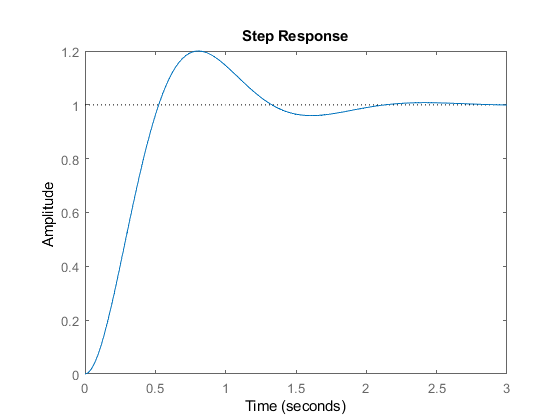

sos = tf([w_n^2],[1 2*zeta_val*w_n w_n^2]); % Second-order system
step(sos);

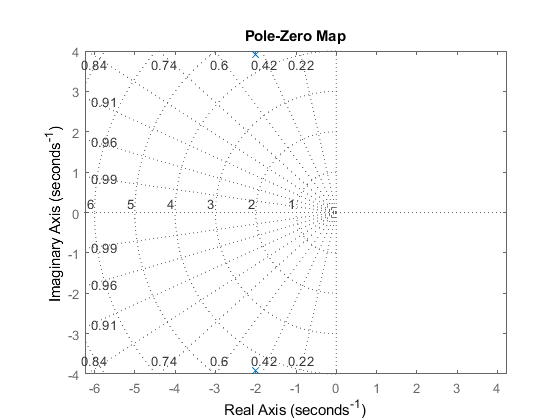

pzmap(sos); grid on;axis('equal')

stepinfo(sos)

ans = struct with fields:
        RiseTime: 0.3552
    SettlingTime: 1.8984
     SettlingMin: 0.9334
     SettlingMax: 1.2000
       Overshoot: 19.9997
      Undershoot: 0
            Peak: 1.2000
        PeakTime: 0.8059


- **Sistema objetivo con 3 polos**

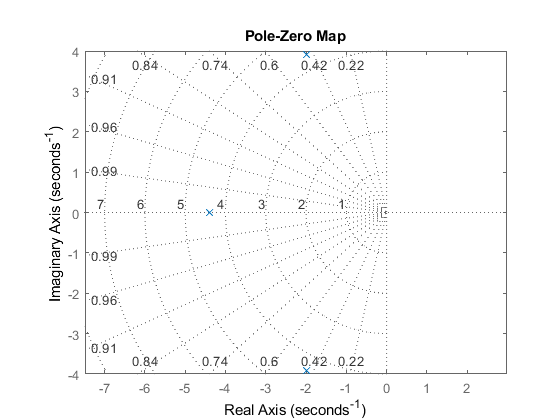

denobjt = conv([1 w_n],[1 2*zeta_val*w_n w_n^2]);
numobjt = [w_n^3];          %w_n^2 para el sos y w_n para el de primer orden
sysobjt = tf(numobjt, denobjt);
pzmap(sysobjt);grid on;axis('equal');

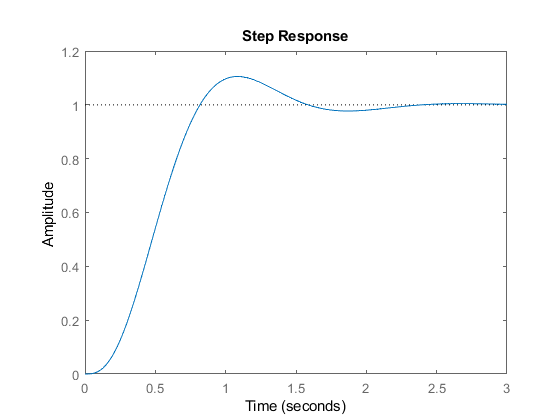

step(sysobjt);

stepinfo(sysobjt)

ans = struct with fields:
        RiseTime: 0.4957
    SettlingTime: 1.9966
     SettlingMin: 0.9149
     SettlingMax: 1.1053
       Overshoot: 10.5255
      Undershoot: 0
            Peak: 1.1053
        PeakTime: 1.0919


- **Sistema objetivo alternativo con 3 polos**

**Pongo los polos conjugados en el mismo lugar y el polo real a una frecuencia mas alta. De modo que el sistema sea dominante de segundo orden.**

%fw_r        = 10;            %frecuencia del polo rápido 10x w_n
fw_r =1.33

fw_r = 1.3300

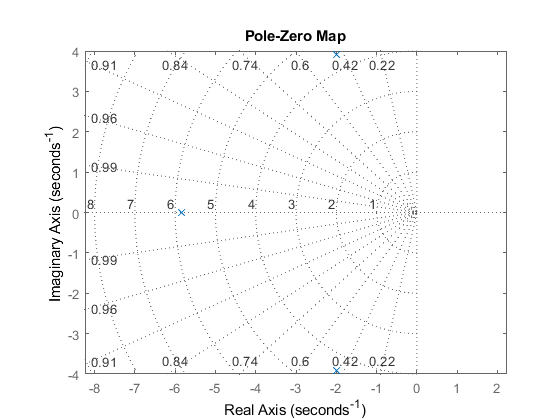

w_r         = fw_r*w_n;      %frecuencia polo rápido
denobjtalt  = conv([1 w_r],[1 2*zeta_val*w_n w_n^2]);
numobjtalt  = [w_n^2*w_r];   %w_n^2 para el sos y w_r para el de primer orden
sysobjtalt  = tf(numobjtalt, denobjtalt);
pzmap(sysobjtalt);grid on;axis('equal');

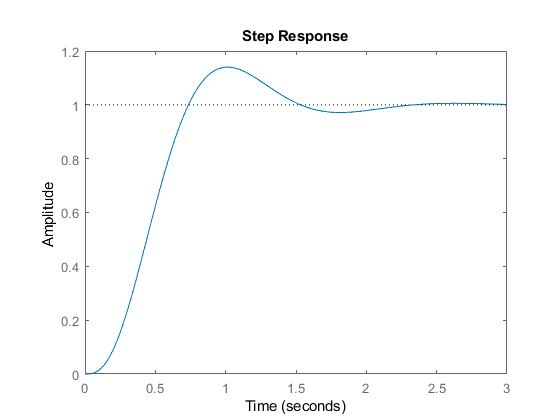

step(sysobjtalt)

stepinfo(sysobjtalt)

ans = struct with fields:
        RiseTime: 0.4494
    SettlingTime: 2.0187
     SettlingMin: 0.9079
     SettlingMax: 1.1402
       Overshoot: 14.0166
      Undershoot: 0
            Peak: 1.1402
        PeakTime: 1.0104


# Asignación de Polos

target_poly = collect(expand((s^2 + 2*w_n*zeta_val*s + w_n^2)*(s + w_r)), s);

- **Polinomio** **objetivo**

disp(target_poly)

$$s^{3}+\frac{11072072036974957\,s^{2}}{1125899906842624}+\frac{11984310889197261\,s}{281474976710656}+\frac{1111680800877483734320885733775}{9903520314283042199192993792}$$

[numGr, denGr]  = numden(Gr);
denGr           = collect(denGr);
denGr_aux       = simplify(denGr/(2*K*a*b + 1));

- **Polinomio** **problema**

disp(denGr_aux);

$$\frac{\left(2\,K\,a\,b+1\right)\,s^{3}+\left(2\,K\,a+2\,K\,b+4\,K\,a\,b+11\right)\,s^{2}+\left(2\,K+4\,K\,a+4\,K\,b+10\right)\,s+4\,K}{2\,K\,a\,b+1}$$

eqs     = coeffs(denGr_aux, s) == coeffs(target_poly, s);

- **Sistema de ecuaciones a resolver**

disp(eqs)

$$\left(\begin{array}{cccc} \frac{4\,K}{2\,K\,a\,b+1}=\frac{1111680800877483734320885733775}{9903520314283042199192993792} & \frac{2\,K+4\,K\,a+4\,K\,b+10}{2\,K\,a\,b+1}=\frac{11984310889197261}{281474976710656} & \frac{2\,K\,a+2\,K\,b+4\,K\,a\,b+11}{2\,K\,a\,b+1}=\frac{11072072036974957}{1125899906842624} & 1=1 \end{array}\right)$$

sol    = solve(eqs, [K, a, b], 'ReturnConditions', true);

K_sol  = double(sol.K);
K_sol  = K_sol(1);
a_sol  = double(sol.a);
a_sol  = a_sol(1);
b_sol  = double(sol.b);
b_sol  = b_sol(1);

- **Solución K**

disp(K_sol)

    7.6840



- **Solución a**

disp(a_sol)

    0.0884



- **Solución b**

disp(b_sol)

   -0.5345



# Verificación de la solución

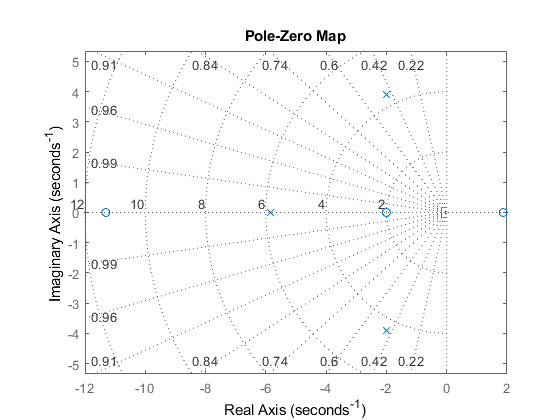

numsol = sym2poly(subs(numGr, [a b K], [a_sol, b_sol, K_sol]));
densol = sym2poly(subs(denGr, [a b K], [a_sol, b_sol, K_sol]));
syssol = tf(numsol, densol);
pzmap(syssol); grid on; axis('equal');

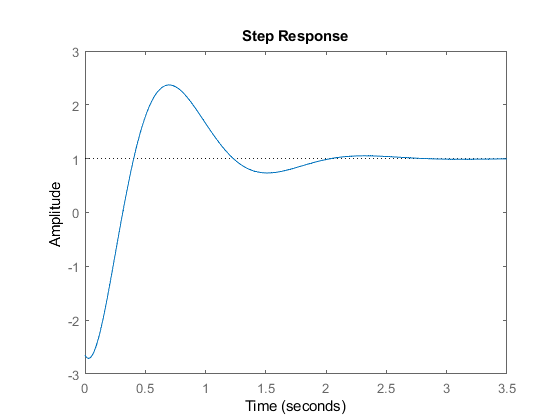

step(syssol);

stepinfo(syssol)

ans = struct with fields:
        RiseTime: 0.2510
    SettlingTime: 1.8912
     SettlingMin: 0.7346
     SettlingMax: 2.3698
       Overshoot: 136.9783
      Undershoot: 271.1420
            Peak: 2.7114
        PeakTime: 0.0316


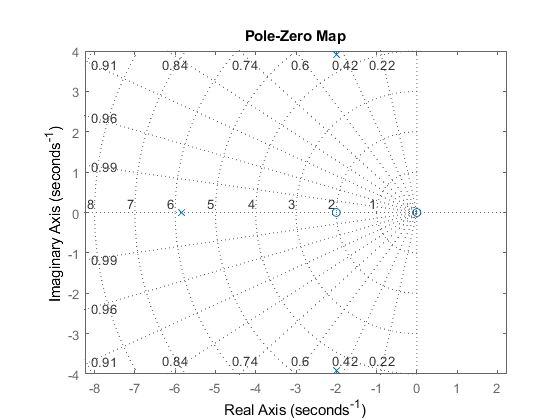

[numGd, denGd] = numden(Gd);
numsol_d = sym2poly(subs(numGd, [a b K], [a_sol, b_sol, K_sol]));
densol_d = sym2poly(subs(denGd, [a b K], [a_sol, b_sol, K_sol]));
syssol_d = tf(numsol_d, densol_d);
pzmap(syssol_d); grid on; axis('equal');

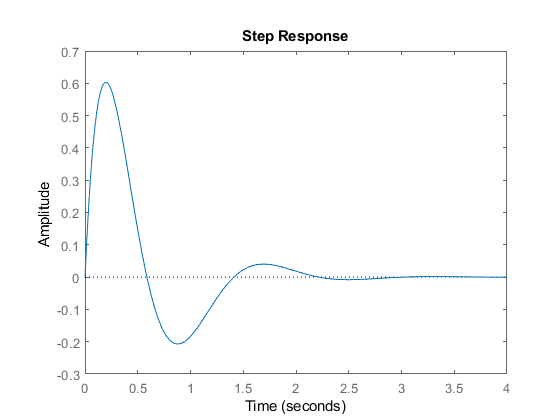

step(syssol_d);

stepinfo(syssol_d)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 2.0631
     SettlingMin: -0.2069
     SettlingMax: 0.6030
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.6030
        PeakTime: 0.2052


# **Análisis/Conclusiones**

**Las características de la respuesta a lazo cerrado del sistema, osea, la dinámica de la respuesta, no depende solamente de la ecuación caracterísitica, osea de la ubicación de los polos del sistema, sino que también depende de la ubicación de los ceros. Eso es evidente cuando se compara la respuesta a un escalón del sistema objetivo especificado solamente por los polos a LC con la respuesta al escalón del sistema obtenido por asignación de polos. Aunque ambos sistemas tienen los mismos polos, las respuestas son claramente diferentes entre sí. En lo que difieren ambos sistemas es en la ubicación de los ceros.**

**Por eso, cuando el sistema objetivo se define con una frecuencia del polo real muy grande comparada con la frecuencia del par conjugado, el mismo sí responde como un sistema de segundo orden equivalente dado que ese par es el par de polos dominante. Sin embargo, el sistema obtenido por asignación de polos tiene una respuesta que difiere mucho de la respuesta de un sistema de segundo orden y eso debido a los ceros.**